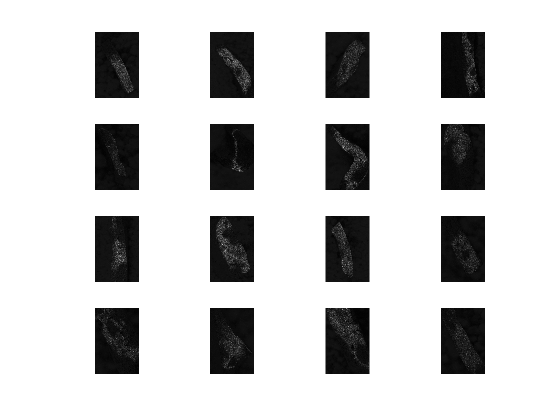

% prepare images as imageDataStore and split 70/30
dStore = imageDatastore('Gabor_Samples','IncludeSubfolders',true,'LabelSource','foldernames');
[trainSet,testSet] = splitEachLabel(dStore,0.7,'randomized');

% display images is this needed?;
numTrainImages = numel(trainSet.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(trainSet,idx(i));
    imshow(I)
end


% load nn, could also load different resnet layers like 50
net = resnet18 

net =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}



% run analyser
inputSize = net.Layers(1).InputSize;
%analyzeNetwork(net)

% resize dataset
size = [244, 224];
augmentTrain = augmentedImageDatastore(inputSize, trainSet);
augmentTest = augmentedImageDatastore(inputSize, testSet);


% feature extraction
layer = 'pool5';
trainFeatures = activations(net, augmentTrain, layer, 'OutputAs', 'rows');

Error using DAGNetwork/activations (line 243)
The spatial dimension sizes [224 224 1] of the input images to layer 'data' must be greater than or equal to the corresponding minimum input dimension sizes of the layer [224 224 3].

testFeatures = activations(net, augmentTest, layer, 'OutputAs', 'rows');
%label extraction
trainLabels = trainSet.Labels;
testLabels = testSet.Labels;

% classify and predict
classifier = fitcecoc(trainFeatures, trainLabels);
potPredict = predict(classifier, testFeatures);

% calculate acuracy
accuracy = mean(potPredict == testLabels);
disp(accuracy)